# Simscape multibody model og Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## Own REGBOT parameters

RA = 6.4/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.008; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
%
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## wheel velocity controller (no balance) PI-regulator

sample (usable) controller values

Kpwv = 15;     % Kp
tiwv = 0.05;   % Tau_i
Kffwv = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)
K_post = 1;
t_post = 1;
t_lead_tw = 0;
t_i_tw = 1;
K_tw = 1;
t_trefw = 1;
num_lead_trefw = 0;
den_lead_trefw = 1;
K_trefw = 1;
s = tf('s');

## Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gwv = minreal(tf(num, den))

Gwv =
 
                  5.351e05 s^3 + 5.351e08 s^2 - 3.873e07 s - 3.873e10
  -----------------------------------------------------------------------------------
  s^6 + 2888 s^5 + 2.213e06 s^4 + 3.435e08 s^3 + 1.417e09 s^2 - 5.737e10 s - 1.306e11
 
Continuous-time transfer function.
Model Properties


## Transfer function from previous exercise

Gwv = tf(2.183,[1 6.651]);

## Bodeplot

pole(Gwv)

ans = -6.6510

isstable(Gwv)

ans = logical
   1


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


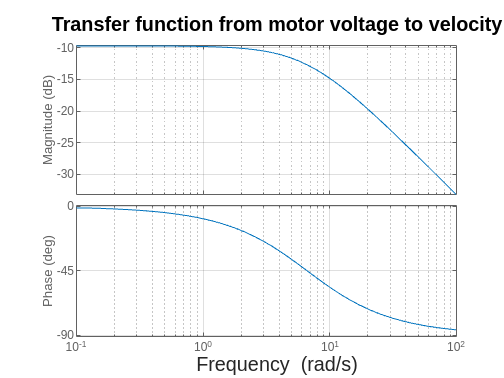

bode(Gwv)
grid on
title('Transfer function from motor voltage to velocity')

% saveas(h, 'motor to velocity.png');

## PI-Controller for voltage to velocity

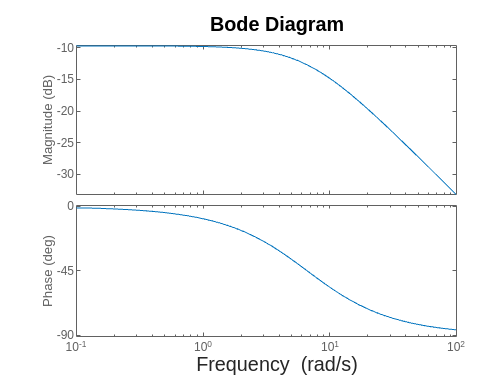

%Design parameters
N_i = 3;
gamma_m = 90;

phi_i = rad2deg(-atan(1/N_i));
phi_G = -180+gamma_m-phi_i;

bode(Gwv)

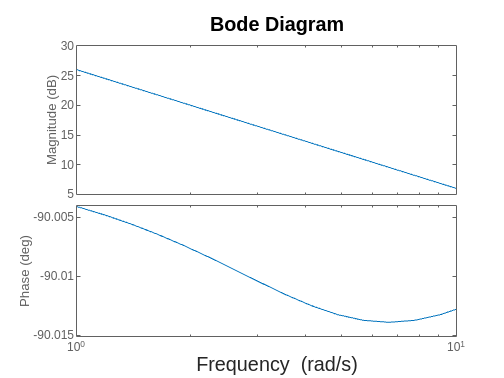


[mag,phase,wout] = bode(Gwv);
omega_c = interp1(squeeze(phase),wout,phi_G);
tau_i = N_i/omega_c;
C_i = tf([tau_i 1],[tau_i 0]);
Kp = 1/abs(freqresp(C_i*Gwv,omega_c*1i));
G_ol = Kp*C_i*Gwv;
G_wv_cl = G_ol/(1+G_ol);
bode(G_ol)

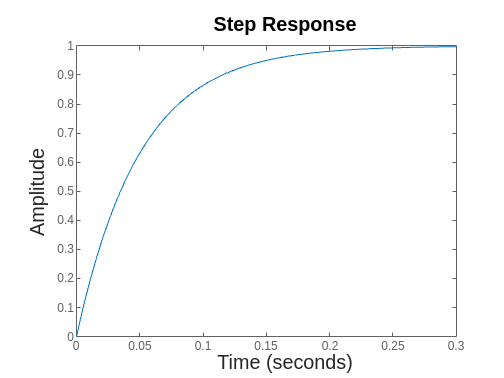

step(G_wv_cl)

## Flush values to model

Kpwv = Kp

Kpwv = 9.1442

tiwv = tau_i

tiwv = 0.1503

## **Transfer function from velocity to tilt using linearize**

% define points in model
ios(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gtw = minreal(tf(num, den))

Gtw =
 
                 -2.737e05 s^4 - 3.544e08 s^3 - 6.192e10 s^2 - 3.966e11 s - 1.187e09
  --------------------------------------------------------------------------------------------------
  s^7 + 2888 s^6 + 2.213e06 s^5 + 3.484e08 s^4 + 6.343e09 s^3 - 2.517e10 s^2 - 4.871e11 s - 2.357e12
 
Continuous-time transfer function.


h = figure(100)

h =   Figure (100) with properties:

      Number: 100
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


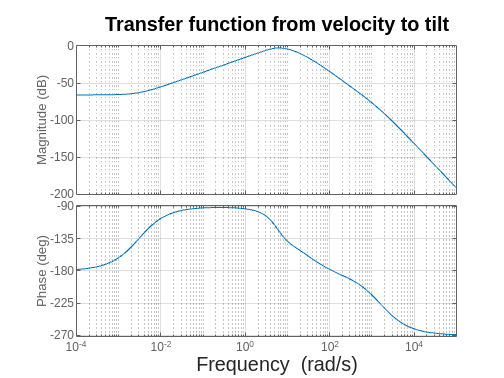

bode(-Gtw)
grid on
title('Transfer function from velocity to tilt')

[mag,phase,wout]=bode(Gtw);

## Post-Integrator

[gpeak,fpeak] = getPeakGain(-Gtw)

gpeak = 0.7318

fpeak = 6.3144

tau_i = 1/fpeak

tau_i = 0.1584

C_pi = -(tau_i*s+1)/(tau_i*s)

C_pi =
 
  -0.1584 s - 1
  -------------
    0.1584 s
 
Continuous-time transfer function.
Model Properties


G_post=Gtw*C_pi

G_post =
 
                4.334e04 s^5 + 5.641e07 s^4 + 1.016e10 s^3 + 1.247e11 s^2 + 3.968e11 s + 1.187e09
  --------------------------------------------------------------------------------------------------------------
  0.1584 s^8 + 457.4 s^7 + 3.504e05 s^6 + 5.518e07 s^5 + 1.004e09 s^4 - 3.986e09 s^3 - 7.714e10 s^2 - 3.732e11 s
 
Continuous-time transfer function.


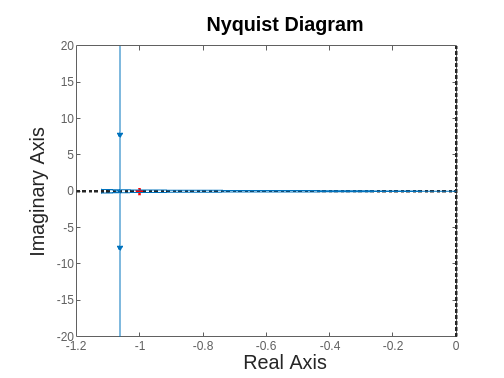

nyquist(G_post)

G_post_cl=minreal(G_post/(1+G_post))

G_post_cl =
 
                  2.737e05 s^5 + 3.562e08 s^4 + 6.416e10 s^3 + 7.876e11 s^2 + 2.506e12 s + 7.497e09
  -----------------------------------------------------------------------------------------------------------------
  s^8 + 2888 s^7 + 2.213e06 s^6 + 3.487e08 s^5 + 6.699e09 s^4 + 3.899e10 s^3 + 3.006e11 s^2 + 1.491e11 s + 7.497e09
 
Continuous-time transfer function.


isstable(G_post_cl)

ans = logical
   1


## Flush values to Simulink

K_post = -1

K_post = -1

t_post=tau_i

t_post = 0.1584

## Tilt controller PI-lead without filter

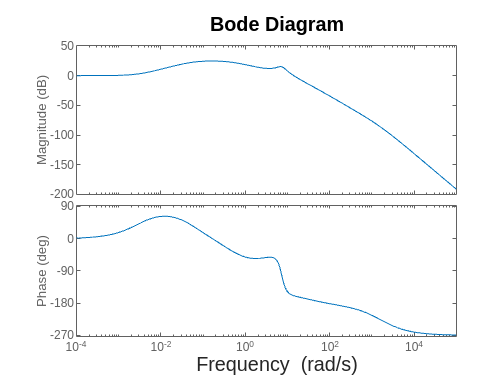

bode(G_post_cl)

% Design parameters
N_i = 10;
gamma_m = 60;
alpha = 0.00001;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_post_cl);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  0.01582 s + 1
  -------------
    0.01582 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
   0.5002 s + 1
  ---------------
  5.002e-06 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_post_cl),omega_c);
Kp = 1/mag;

G_tw_ol = minreal(Kp*C_i*C_D*G_post_cl)

G_tw_ol =
 
              2.098e11 s^7 + 2.867e14 s^6 + 6.701e16 s^5 + 3.846e18 s^4 + 4.751e19 s^3 + 2.016e20 s^2 + 2.431e20 s + 7.262e17
  ----------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.028e05 s^9 + 5.796e08 s^8 + 4.427e11 s^7 + 6.972e13 s^6 + 1.339e15 s^5 + 7.796e15 s^4 + 6.009e16 s^3 + 2.98e16 s^2 + 1.499e15 s
 
Continuous-time transfer function.


G_tw_cl = minreal(G_tw_ol/(1+G_tw_ol))

G_tw_cl =
 
                    2.098e11 s^7 + 2.867e14 s^6 + 6.701e16 s^5 + 3.846e18 s^4 + 4.751e19 s^3 + 2.016e20 s^2 + 2.431e20 s + 7.262e17
  ----------------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 2.028e05 s^9 + 5.796e08 s^8 + 6.525e11 s^7 + 3.564e14 s^6 + 6.835e16 s^5 + 3.853e18 s^4 + 4.757e19 s^3 + 2.016e20 s^2 + 2.431e20 s + 7.262e17
 
Continuous-time transfer function.


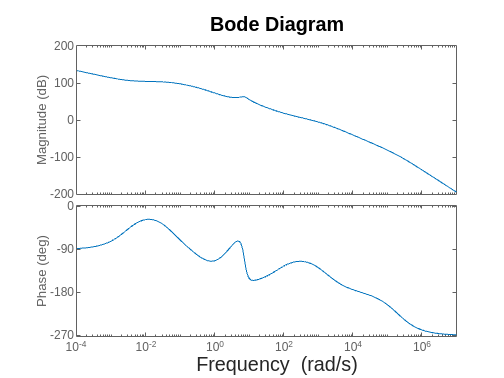


bode(G_tw_ol)

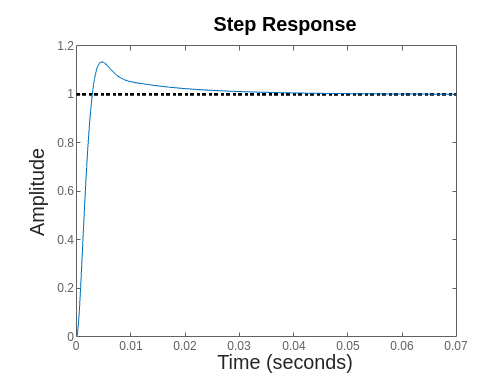

step(G_tw_cl)

## Flush values to simulink

t_lead_tw = tau_D;
t_i_tw = tau_i;
K_tw = Kp;

## Transfer function from reference tilt to velocity using linearize

% define points in model
ios(1) = linio(strcat(model,'/tilt_ref'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_tref_w = minreal(tf(num, den))

G_tref_w =
 
                  -3.751e07 s^6 - 4.036e10 s^5 - 2.887e12 s^4 - 2.95e13 s^3 + 1.095e14 s^2 + 2.347e15 s + 7.21e15
  --------------------------------------------------------------------------------------------------------------------------------
  s^9 + 2888 s^8 + 3.262e06 s^7 + 1.778e09 s^6 + 3.366e11 s^5 + 1.918e13 s^4 + 2.375e14 s^3 + 1.008e15 s^2 + 1.216e15 s + 3.633e12
 
Continuous-time transfer function.


## Reference tilt to velocity controller

isstable(G_tref_w)

ans = logical
   1


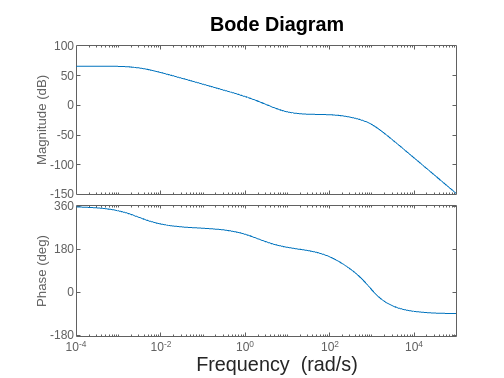

bode(G_tref_w)



% Design parameters
N_i = 6;
gamma_m = 360+70;
alpha = 0.1;


phi_i = rad2deg(-atan(1/N_i));
phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_i - phi_m - 180;
[mag,phase,wout] = bode(G_tref_w);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));
tau_i = N_i/omega_c;

C_i = tf([tau_i 1],[tau_i 0])

C_i =
 
  1.433 s + 1
  -----------
    1.433 s
 
Continuous-time transfer function.
Model Properties


C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  0.755 s + 1
  ------------
  0.0755 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_i*C_D*G_tref_w),omega_c);
Kp = 1/mag;

G_tref_w_ol = minreal(Kp*C_i*C_D*G_tref_w)

G_tref_w_ol =
 
            -1.541e08 s^8 - 1.662e11 s^7 - 1.22e13 s^6 - 1.454e14 s^5 + 1.939e14 s^4 + 1.044e16 s^3 + 4.954e16 s^2 + 6.883e16 s + 2.739e16
  ---------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2901 s^10 + 3.3e06 s^9 + 1.821e09 s^8 + 3.602e11 s^7 + 2.364e13 s^6 + 4.915e14 s^5 + 4.154e15 s^4 + 1.457e16 s^3 + 1.611e16 s^2 + 4.811e13 s
 
Continuous-time transfer function.


G_tref_w_cl = minreal(G_tref_w_ol/(1+G_tref_w_ol))

G_tref_w_cl =
 
                 -1.541e08 s^8 - 1.662e11 s^7 - 1.22e13 s^6 - 1.454e14 s^5 + 1.939e14 s^4 + 1.044e16 s^3 + 4.954e16 s^2 + 6.883e16 s + 2.739e16
  -------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 2901 s^10 + 3.3e06 s^9 + 1.667e09 s^8 + 1.94e11 s^7 + 1.144e13 s^6 + 3.462e14 s^5 + 4.348e15 s^4 + 2.501e16 s^3 + 6.565e16 s^2 + 6.888e16 s + 2.739e16
 
Continuous-time transfer function.


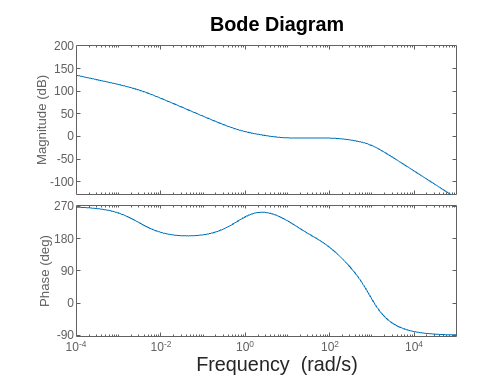


bode(G_tref_w_ol)

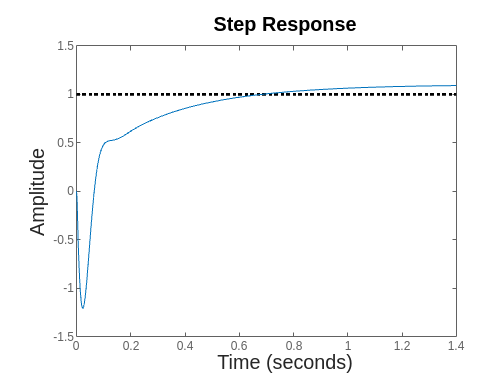

step(G_tref_w_cl)

## Flush values to simulink

t_trefw = tau_i;
[num_lead_trefw,den_lead_trefw] = tfdata(C_D,'v');
K_trefw = Kp;

## Transfer function from vel_pre to x

% define points in model
ios(1) = linio(strcat(model,'/vel_pre'),1,'openinput');
ios(2) = linio(strcat(model, '/x_pos'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
G_wx = minreal(tf(num, den))

G_wx =
 
          -7.705e04 s^9 - 9.947e07 s^8 - 2.396e10 s^7 - 1.579e12 s^6 - 3.063e13 s^5 - 1.485e14 s^4 + 1.485e15 s^3 + 1.828e16 s^2 + 6.206e16 s + 5.621e16
  --------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 2901 s^11 + 3.3e06 s^10 + 1.672e09 s^9 + 1.989e11 s^8 + 1.141e13 s^7 + 3.373e14 s^6 + 4.24e15 s^5 + 2.519e16 s^4 + 7.317e16 s^3 + 1e17 s^2 + 5.621e16 s
 
Continuous-time transfer function.


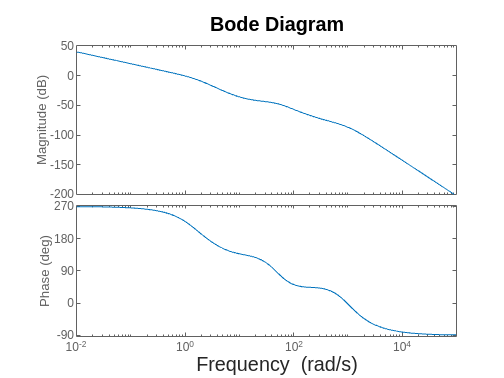

bode(G_wx)

isstable(G_wx)

ans = logical
   0


pole(G_wx)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.2056 + 0.0000i
  -0.7781 + 0.6519i
  -0.7781 - 0.6519i
  -0.0354 + 0.0369i
  -0.0354 - 0.0369i
  -0.0494 + 0.0000i
  -0.0070 + 0.0000i
  -0.0059 + 0.0000i
  -0.0037 + 0.0000i




% Design parameters
gamma_m = 360+60;
alpha = 0.1;

phi_m = rad2deg(asin((1-alpha)/(1+alpha)));

phi_G = gamma_m - phi_m - 180;
[mag,phase,wout] = bode(G_wx);
omega_c = interp1(squeeze(phase),wout,phi_G);

tau_D = 1/(omega_c*sqrt(alpha));

C_D = tf([tau_D 1], [tau_D*alpha 1])

C_D =
 
  1.358 s + 1
  ------------
  0.1358 s + 1
 
Continuous-time transfer function.
Model Properties


[mag,phase] = bode((C_D*G_wx),omega_c);
Kp = 1/mag;

G_wx_ol = minreal(Kp*C_D*G_wx)

G_wx_ol =
 
              -9.704e05 s^10 - 1.253e09 s^9 - 3.027e11 s^8 - 2.011e13 s^7 - 4.003e14 s^6 - 2.154e15 s^5 + 1.732e16 s^4 + 2.439e17 s^3 + 9.51e17 s^2 + 1.283e18 s + 5.211e17
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2909 s^12 + 3.322e06 s^11 + 1.696e09 s^10 + 2.112e11 s^9 + 1.288e13 s^8 + 4.214e14 s^7 + 6.724e15 s^6 + 5.641e16 s^5 + 2.586e17 s^4 + 6.387e17 s^3 + 7.925e17 s^2 + 4.138e17 s
 
Continuous-time transfer function.


G_wx_cl = minreal(G_wx_ol/(1+G_wx_ol))

G_wx_cl =
 
                   -9.704e05 s^13 - 1.273e09 s^12 - 3.282e11 s^11 - 2.642e13 s^10 - 8.498e14 s^9 - 1.311e16 s^8 - 8.712e16 s^7 + 1.793e17 s^6 + 7.606e18 s^5 + 5.914e19 s^4 + 2.307e20 s^3 + 4.755e20 s^2 + 4.622e20 s + 1.588e20
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^16 + 2929 s^15 + 3.381e06 s^14 + 1.763e09 s^13 + 2.447e11 s^12 + 1.706e13 s^11 + 6.854e14 s^10 + 1.624e16 s^9 + 2.411e17 s^8 + 2.361e18 s^7 + 1.581e19 s^6 + 7.384e19 s^5 + 2.416e20 s^4 + 5.419e20 s^3 + 7.735e20 s^2 + 5.883e20 s + 1.588e20
 
Continuous-time transfer function.


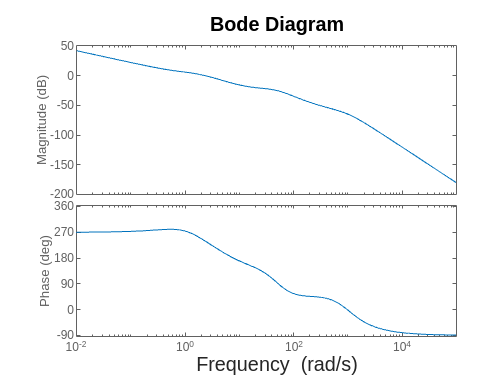


bode(G_wx_ol)

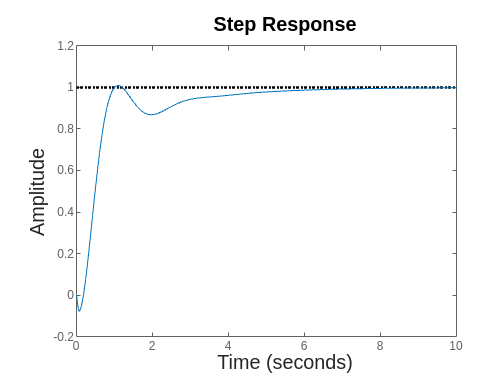

step(G_wx_cl)

## Flush values to Simulink

[num_lead_wx,den_lead_wx] = tfdata(C_D,'v');
K_wx = Kp;